% 用超松弛迭代法求二维静电场域的电位分布
hx=25;hy=17;                    % 设置网格节点数
v1=ones(hy,hx);                 % 设置行列二维数组
v1(1:6,1:9)=zeros(6,9);     % 1到6行的1到9列电位为0
m=24;n=16;                      % 横纵向网格数

% 边界的 Dirichlet 边界条件值
v1(1,10:25)=ones(1,16)*100;      % 第1行电位为100V
v1(2:16,25)=ones(15,1)*50;       % 第25列电位为50V
v1(17,1:25)=0;        % 第17行电位为0
v1(2:7,10)=ones(6,1)*50;        % 纵向50V边界    
v1(7,2:10)=ones(1,9)*50;        % 横向50V边界

% 计算加速收敛因子
t1=(cos(pi/m)+cos(pi/n))/2;
w=2/(1+sqrt(1-t1*t1));

% 超松弛迭代法
v2=v1;maxt=1;t=0;                       % 初始化
k=0;
while(maxt>1e-6)                        % 由 v1 迭代，算出 v2，迭代精度为 0.000001
    k=k+1                               % 计算迭代次数
    maxt=0;
    for i=2:7                          % 从 2 到 6 行循环
        for j=11:24                      % 从 11 到 24 列循环
            v2(i,j)=v1(i,j)+(v1(i,j+1)+v1(i+1,j)+v2(i-1,j)+v2(i,j-1)-4*v1(i,j))*w/4;%拉普拉斯方程差分式
            t=abs(v2(i,j)-v1(i,j));
            if(t>maxt) maxt=t;
                end
        end
    end
    for i=8:16                          % 从 7 到 16 行循环
        for j=2:24                       % 从 2 到 24 列循环
            v2(i,j)=v1(i,j)+(v1(i,j+1)+v1(i+1,j)+v2(i-1,j)+v2(i,j-1)-4*v1(i,j))*w/4;%拉普拉斯方程差分式
            t=abs(v2(i,j)-v1(i,j));
            if(t>maxt) maxt=t;
                end
        end
    end
    v2(7:16,1)=v2(7:16,2);               % Neumann 条件处理
    v1=v2                                % 迭代一次
end

k = 1

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   64.4614   70.6623   73.3212   74.4614   74.9503   75.1599   75.2498   75.2883   75.3048   75.3119   75.3150   75.3163   75.3168   96.3279   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   49.2227   51.5483   53.6856   55.0910   55.9032   56.3414   56.5678   56.6814   56.7372   56.7642   56.7770   56.7831   56.7860   86.8075   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   42.6884   40.5505   40.5502   41.1527   41.7593   42.2073   42.4965   42.6692   42.7672   42.8208   42.8493   42.8641   42.8717   76.7588  

k = 2

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   69.6238   75.7410   77.8677   78.7765   79.2547   79.5363   79.7063   79.8075   79.8660   79.8989   79.9169   79.9266   88.9409   70.7876   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.4992   60.2456   61.8378   62.5118   62.8730   63.1244   63.3159   63.4582   63.5579   63.6240   63.6657   63.6909   80.4413   57.1169   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   49.6274   50.3503   50.6357   50.5729   50.4405   50.3695   50.3736   50.4230   50.4871   50.5470   50.5947   50.6291   72.3573   51.2063  

k = 3

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   71.2296   78.4762   81.1350   82.1192   82.4748   82.6066   82.6670   82.7066   82.7387   82.7649   82.7853   86.6633   81.2777   73.0363   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6885   63.8349   66.4542   67.6453   68.1013   68.2252   68.2300   68.2113   68.2015   68.2049   68.2165   77.0635   65.8839   62.1161   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   52.2694   54.2749   55.5683   56.2504   56.5013   56.4992   56.3872   56.2563   56.1505   56.0815   56.0447   69.1246   55.8648   56.2633  

k = 4

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.1928   79.8731   82.8101   84.0288   84.5491   84.7570   84.8219   84.8272   84.8136   84.7991   86.4462   85.8633   81.1373   73.5115   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   60.2077   66.1806   69.1931   70.6436   71.3232   71.6164   71.7104   71.7061   71.6614   71.6091   76.0624   72.2096   69.2252   62.3457   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   53.9651   57.1116   59.0003   59.9635   60.3933   60.5455   60.5551   60.4921   60.3970   60.2962   67.7491   61.1439   61.4994   56.8183  

k = 5

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   72.7544   80.8390   84.0195   85.3568   85.9386   86.1930   86.2982   86.3319   86.3307   87.0243   87.8034   84.8759   82.4508   73.8333   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.0949   67.6883   71.1567   72.8844   73.6987   74.0528   74.1848   74.2127   74.1930   76.3856   76.0187   73.2495   70.3593   63.0438   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   54.8991   58.5583   60.8747   62.2313   62.9695   63.3300   63.4739   63.5029   63.4753   67.6141   65.3703   64.8783   62.3381   57.5725  

k = 6

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.1474   81.4818   84.8416   86.3162   86.9906   87.2948   87.4211   87.4626   87.7702   88.6803   87.1007   86.2899   82.7420   74.0274   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   61.6760   68.5972   72.2592   74.1569   75.1460   75.6583   75.9115   76.0218   77.1435   78.0640   75.8942   75.1463   71.1453   63.2882   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.5167   59.6780   62.3388   63.9095   64.8038   65.3039   65.5754   65.7115   68.0310   68.1123   67.0656   66.3816   63.4961   57.9014  

k = 7

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.3911   81.8688   85.3038   86.8249   87.5494   87.9164   88.1098   88.3422   89.0931   88.4817   88.0710   86.6328   83.1011   74.1474   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.0194   69.2133   73.1065   75.1685   76.2592   76.8408   77.1558   77.8509   79.0581   77.7596   77.8091   75.7396   71.5929   63.4978   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   55.9983   60.5009   63.4344   65.2360   66.3072   66.9279   67.2794   68.6696   69.7246   68.6952   69.0932   67.4395   63.9611   58.1377  

k = 8

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.5300   82.1140   85.6598   87.2872   88.0919   88.5068   88.7811   89.3526   89.3160   89.0048   88.5696   87.0097   83.2493   74.2149   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.3041   69.7160   73.7723   75.9749   77.1931   77.8786   78.5138   79.6477   79.1505   79.3123   78.4430   76.3942   71.9062   63.6126   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.3761   61.1902   64.3595   66.3319   67.5376   68.2736   69.3406   70.7042   70.0912   70.8528   70.0345   68.1765   64.4337   58.3305  

k = 9

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.6578   82.3617   85.9951   87.6787   88.5254   89.0033   89.5294   89.8169   89.6197   89.6404   88.9190   87.2342   83.4029   74.2817   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.5329   70.1419   74.3650   76.6906   77.9906   78.8506   79.9345   80.0831   80.2243   80.1319   79.1752   76.7867   72.1682   63.7541   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.6958   61.7633   65.1390   67.2796   68.6121   69.7516   71.1940   71.1524   71.9167   71.7731   70.9726   68.7613   64.7820   58.5202  

k = 10

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.7707   82.5593   86.2621   88.0060   88.9106   89.5510   90.0374   90.0195   90.2224   89.9455   89.2102   87.4327   83.5191   74.3445   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.7374   70.5096   74.8544   77.2773   78.7145   79.9437   80.5863   80.7907   81.1524   80.7831   79.6262   77.1476   72.3954   63.8586   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   56.9683   62.2617   65.8104   68.0789   69.6700   71.2687   71.8240   72.5390   72.9307   72.7434   71.5865   69.2300   65.1036   58.6586  

k = 11

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.8624   82.7294   86.4943   88.2882   89.3014   90.0134   90.2388   90.5228   90.5359   90.2659   89.4178   87.5843   83.6254   74.3900   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   62.9049   70.8149   75.2743   77.8119   79.5159   80.6339   81.0760   81.7029   81.7283   81.3111   80.0371   77.4291   72.5819   63.9427   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.2017   62.6815   66.3801   68.8491   70.8471   72.0050   72.8080   73.6090   73.8102   73.4011   72.1524   69.6377   65.3518   58.7758  

k = 12

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   73.9416   82.8723   86.6905   88.5674   89.6835   90.2289   90.6129   90.8489   90.8358   90.4808   89.6026   87.7214   83.7076   74.4288   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.0501   71.0801   75.6454   78.3822   80.1518   81.0310   81.8696   82.2364   82.2773   81.7192   80.3608   77.6802   72.7340   64.0146   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.4015   63.0478   66.9173   69.7117   71.5834   72.7124   73.8511   74.3806   74.5115   73.9949   72.6018   69.9705   65.5632   58.8751  

k = 13

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0085   82.9966   86.8823   88.8583   89.9001   90.4984   90.9410   91.1137   91.0625   90.6785   89.7528   87.8307   83.7775   74.4618   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.1743   71.3132   76.0371   78.9097   80.5021   81.6564   82.3870   82.7565   82.6806   82.0785   80.6481   77.8785   72.8617   64.0747   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.5743   63.3794   67.5083   70.3594   72.1047   73.6135   74.5153   75.0633   75.0672   74.4563   72.9756   70.2266   65.7165   58.9341  

k = 14

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.0672   83.1151   87.0887   89.0578   90.0964   90.7987   91.1705   91.3430   91.2564   90.8387   89.8842   87.9239   83.8364   74.4892   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.2847   71.5548   76.4286   79.2138   80.9579   82.1415   82.8312   83.1390   83.0317   82.3618   80.8658   78.0346   72.9540   64.1084   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.7313   63.7510   68.0246   70.7619   72.8203   74.2060   75.1346   75.5664   75.5191   74.8252   73.2386   70.4018   65.8039   58.9635  

k = 15

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1233   83.2465   87.2508   89.1993   90.3409   90.9952   91.3794   91.5158   91.4110   90.9683   89.9791   87.9901   83.8740   74.5002   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.4007   71.8154   76.6817   79.5335   81.3887   82.5081   83.1898   83.4596   83.2996   82.5812   81.0246   78.1342   72.9988   64.1208   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   57.9145   64.1069   68.3225   71.2710   73.3285   74.7091   75.5709   75.9772   75.8590   75.0907   73.4348   70.5219   65.8727   59.0045  

k = 16

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.1893   83.3621   87.3536   89.3840   90.5143   91.1758   91.5353   91.6628   91.5339   91.0631   90.0483   88.0313   83.8887   74.5039   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.5364   71.9978   76.8878   79.8755   81.6767   82.8163   83.4569   83.6989   83.5031   82.7341   81.1331   78.1978   73.0352   64.1467   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1005   64.3058   68.6535   71.6966   73.7286   75.1043   75.9473   76.3059   76.1408   75.3124   73.5914   70.6257   65.9340   59.0122  

k = 17

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2498   83.4276   87.4758   89.5253   90.6518   91.3046   91.6567   91.7650   91.6178   91.1265   90.0902   88.0534   83.9049   74.5193   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6233   72.1064   77.1279   80.1004   81.9298   83.0437   83.6795   83.8952   83.6641   82.8626   81.2229   78.2604   73.0803   64.1574   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.1791   64.4804   68.9812   72.0089   74.0804   75.4387   76.2614   76.5878   76.3699   75.4882   73.7012   70.6680   65.9149   58.9945  

k = 18

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2719   83.4892   87.5784   89.6236   90.7594   91.4081   91.7535   91.8535   91.6920   91.1860   90.1337   88.0901   83.9350   74.5258   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.6508   72.2448   77.2965   80.2965   82.1273   83.2490   83.8687   84.0639   83.8065   82.9712   81.2978   78.3010   73.0747   64.1426   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.2388   64.6971   69.2071   72.2919   74.3578   75.7218   76.5231   76.8114   76.5538   75.5836   73.7058   70.6215   65.8919   58.9946  

k = 19

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.2944   83.5581   87.6490   89.7138   90.8502   91.5026   91.8439   91.9331   91.7596   91.2377   90.1726   88.1108   83.9227   74.5095   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.7257   72.3727   77.4420   80.4633   82.3035   83.4208   84.0303   84.2035   83.9189   83.0369   81.3085   78.2631   73.0410   64.1318   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.3778   64.8721   69.4316   72.5244   74.6054   75.9546   76.7327   76.9911   76.6134   75.5401   73.6421   70.6069   65.8989   58.9967  

k = 20

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3400   83.6135   87.7233   89.7916   90.9347   91.5836   91.9174   91.9966   91.8088   91.2667   90.1707   88.0737   83.8941   74.5043   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8061   72.4769   77.5823   80.6128   82.4577   83.5679   84.1591   84.3114   83.9596   83.0057   81.2432   78.2255   73.0351   64.1356   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4658   65.0203   69.6177   72.7334   74.8119   76.1503   76.9049   77.0048   76.5291   75.4797   73.6439   70.6158   65.8967   58.9947  

k = 21

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3656   83.6614   87.7843   89.8625   91.0055   91.6506   91.9760   92.0437   91.8237   91.2381   90.1159   88.0483   83.8989   74.5117   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8420   72.5620   77.6884   80.7375   82.5829   83.6843   84.2621   84.3219   83.8919   82.9328   81.2198   78.2328   73.0452   64.1396   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5162   65.1259   69.7550   72.8903   74.9748   76.3032   76.8648   76.8972   76.4907   75.4955   73.6472   70.6101   65.8982   58.9987  

k = 22

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3832   83.6973   87.8319   89.9161   91.0603   91.7012   92.0202   92.0398   91.7701   91.1808   90.1096   88.0689   83.9119   74.5137   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8820   72.6245   77.7721   80.8281   82.6755   83.7721   84.2324   84.2248   83.8280   82.9297   81.2370   78.2457   73.0514   64.1419   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5754   65.2163   69.8724   73.0174   75.0997   76.2017   76.7463   76.8791   76.5029   75.4865   73.6433   70.6194   65.9065   59.0010  

k = 23

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4032   83.7275   87.8696   89.9562   91.0997   91.7385   91.9902   91.9651   91.7244   91.1982   90.1378   88.0773   83.9097   74.5124   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9142   72.6811   77.8419   80.9047   82.7502   83.7011   84.1178   84.1780   83.8379   82.9472   81.2481   78.2515   73.0531   64.1414   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6175   65.2977   69.9725   73.1249   74.9546   76.0980   76.7460   76.8772   76.4853   75.4889   73.6562   70.6249   65.9058   58.9996  

k = 24

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4156   83.7517   87.9002   89.9904   91.1342   91.6833   91.9068   91.9431   91.7594   91.2203   90.1355   88.0719   83.9091   74.5128   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9388   72.7264   77.9003   80.9677   82.6459   83.5899   84.0961   84.1962   83.8535   82.9567   81.2513   78.2495   73.0503   64.1401   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6560   65.3602   70.0510   72.9395   74.8727   76.1023   76.7287   76.8634   76.4980   75.5012   73.6564   70.6211   65.9031   58.9983  

k = 25

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4277   83.7721   87.9267   90.0192   91.0534   91.6048   91.9140   91.9847   91.7684   91.2115   90.1323   88.0733   83.9091   74.5119   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9623   72.7647   77.9470   80.8308   82.5444   83.5847   84.1129   84.2090   83.8612   82.9560   81.2466   78.2467   73.0494   64.1397   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6873   65.4140   69.8401   72.8805   74.8651   76.0696   76.7209   76.8777   76.5022   75.4956   73.6514   70.6185   65.9015   58.9977  

k = 26

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4378   83.7896   87.9477   89.9142   90.9890   91.6342   91.9465   91.9783   91.7587   91.2120   90.1334   88.0716   83.9076   74.5118   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9797   72.7954   77.7866   80.7461   82.5476   83.5956   84.1216   84.2102   83.8536   82.9490   81.2441   78.2453   73.0479   64.1391   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.7122   65.1855   69.7970   72.8531   74.8265   76.0692   76.7297   76.8716   76.4918   75.4889   73.6471   70.6152   65.8993   58.9965  

k = 27

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4455   83.8025   87.8245   89.8725   91.0311   91.6498   91.9309   91.9726   91.7601   91.2097   90.1298   88.0701   83.9073   74.5115   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9944   72.6185   77.7179   80.7489   82.5527   83.6003   84.1150   84.1982   83.8471   82.9463   81.2408   78.2422   73.0463   64.1382   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.4774   65.1500   69.7467   72.8136   74.8269   76.0665   76.7151   76.8590   76.4839   75.4830   73.6421   70.6113   65.8968   58.9951  

k = 28

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4519   83.6674   87.8072   89.9142   91.0278   91.6326   91.9294   91.9715   91.7549   91.2064   90.1289   88.0693   83.9064   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.8101   72.5633   77.7156   80.7491   82.5499   83.5843   84.1008   84.1920   83.8423   82.9408   81.2369   78.2400   73.0447   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6352   65.2276   69.8138   72.8775   74.8547   76.0715   76.7150   76.8569   76.4800   75.4781   73.6378   70.6082   65.8946   58.9941  

k = 29

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.3103   83.6723   87.8386   89.8965   91.0140   91.6315   91.9235   91.9648   91.7523   91.2049   90.1269   88.0677   83.9054   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9252   72.6866   77.8124   80.8090   82.5767   83.6028   84.1137   84.1961   83.8423   82.9404   81.2359   78.2384   73.0434   64.1368   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.5776   65.2175   69.8290   72.8858   74.8646   76.0854   76.7275   76.8653   76.4847   75.4807   73.6390   70.6083   65.8945   58.9943  

k = 30

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4630   83.8005   87.9051   89.9574   91.0610   91.6578   91.9417   91.9780   91.7592   91.2079   90.1285   88.0684   83.9057   74.5107   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9365   72.6954   77.8076   80.8054   82.5883   83.6173   84.1257   84.2076   83.8520   82.9468   81.2398   78.2411   73.0453   64.1381   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6235   65.2572   69.8434   72.8914   74.8684   76.0881   76.7300   76.8690   76.4895   75.4854   73.6429   70.6116   65.8974   58.9965  

k = 31

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4137   83.7199   87.8471   89.9076   91.0222   91.6364   91.9303   91.9716   91.7569   91.2082   90.1295   88.0696   83.9069   74.5116   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9308   72.6671   77.7786   80.7815   82.5610   83.5924   84.1075   84.1946   83.8433   82.9423   81.2383   78.2413   73.0464   64.1390   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6103   65.2300   69.8191   72.8721   74.8506   76.0713   76.7155   76.8568   76.4796   75.4782   73.6387   70.6099   65.8971   58.9960  

k = 32

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4120   83.7398   87.8632   89.9233   91.0358   91.6419   91.9302   91.9696   91.7541   91.2053   90.1274   88.0684   83.9064   74.5112   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9163   72.6655   77.7850   80.7881   82.5708   83.6019   84.1127   84.1964   83.8430   82.9404   81.2359   78.2393   73.0448   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6037   65.2284   69.8208   72.8739   74.8538   76.0761   76.7198   76.8596   76.4811   75.4785   73.6380   70.6086   65.8952   58.9940  

k = 33

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4155   83.7334   87.8584   89.9186   91.0307   91.6398   91.9308   91.9708   91.7552   91.2061   90.1278   88.0683   83.9058   74.5105   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9247   72.6696   77.7836   80.7858   82.5661   83.5964   84.1094   84.1952   83.8430   82.9413   81.2370   78.2400   73.0444   64.1372   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6062   65.2305   69.8206   72.8731   74.8518   76.0721   76.7157   76.8567   76.4794   75.4781   73.6385   70.6091   65.8951   58.9948  

k = 34

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7369   87.8608   89.9198   91.0319   91.6397   91.9295   91.9694   91.7542   91.2056   90.1277   88.0684   83.9058   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6668   77.7834   80.7855   82.5666   83.5974   84.1094   84.1942   83.8417   82.9402   81.2363   78.2392   73.0443   64.1378   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6050   65.2282   69.8191   72.8714   74.8502   76.0718   76.7158   76.8565   76.4789   75.4774   73.6375   70.6079   65.8950   58.9949  

k = 35

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4149   83.7347   87.8585   89.9184   91.0306   91.6391   91.9295   91.9695   91.7542   91.2055   90.1274   88.0679   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9223   72.6674   77.7821   80.7840   82.5648   83.5955   84.1083   84.1939   83.8418   82.9403   81.2360   78.2389   73.0444   64.1373   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6050   65.2285   69.8183   72.8704   74.8492   76.0703   76.7142   76.8555   76.4786   75.4774   73.6373   70.6080   65.8952   58.9946  

k = 36

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7351   87.8592   89.9185   91.0306   91.6387   91.9289   91.9690   91.7540   91.2054   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9210   72.6661   77.7818   80.7838   82.5647   83.5955   84.1080   84.1934   83.8414   82.9398   81.2357   78.2391   73.0444   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6044   65.2271   69.8174   72.8697   74.8486   76.0700   76.7143   76.8555   76.4784   75.4768   73.6369   70.6081   65.8950   58.9948  

k = 37

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4142   83.7347   87.8585   89.9180   91.0302   91.6386   91.9289   91.9691   91.7539   91.2052   90.1272   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9213   72.6663   77.7813   80.7832   82.5641   83.5949   84.1078   84.1935   83.8414   82.9397   81.2358   78.2391   73.0443   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6042   65.2272   69.8171   72.8692   74.8481   76.0696   76.7139   76.8554   76.4783   75.4769   73.6373   70.6081   65.8952   58.9948  

k = 38

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4139   83.7346   87.8585   89.9179   91.0301   91.6384   91.9288   91.9690   91.7539   91.2052   90.1273   88.0680   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7811   80.7830   82.5640   83.5950   84.1078   84.1933   83.8412   82.9398   81.2359   78.2391   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6041   65.2267   69.8167   72.8689   74.8480   76.0696   76.7141   76.8554   76.4782   75.4770   73.6374   70.6083   65.8953   58.9949  

k = 39

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4139   83.7345   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7538   91.2053   90.1273   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9210   72.6658   77.7808   80.7828   82.5639   83.5949   84.1078   84.1934   83.8414   82.9400   81.2360   78.2393   73.0445   64.1376   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8167   72.8689   74.8480   76.0697   76.7141   76.8554   76.4784   75.4772   73.6375   70.6084   65.8953   58.9948  

k = 40

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0300   91.6384   91.9288   91.9690   91.7539   91.2053   90.1274   88.0682   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6656   77.7808   80.7829   82.5640   83.5950   84.1078   84.1934   83.8415   82.9400   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8166   72.8689   74.8481   76.0698   76.7141   76.8555   76.4785   75.4772   73.6376   70.6083   65.8953   58.9948  

k = 41

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7344   87.8582   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0682   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7808   80.7829   82.5641   83.5951   84.1079   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8482   76.0698   76.7142   76.8556   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 42

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9058   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9208   72.6657   77.7809   80.7830   82.5641   83.5951   84.1079   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8690   74.8482   76.0698   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 43

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5951   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2266   69.8167   72.8691   74.8482   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.9948  

k = 44

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6657   77.7809   80.7830   82.5641   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6039   65.2267   69.8168   72.8691   74.8483   76.0700   76.7144   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.9948  

k = 45

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9178   91.0301   91.6386   91.9289   91.9692   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0700   76.7144   76.8557   76.4786   75.4773   73.6375   70.6083   65.8952   58.9948  

k = 46

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9290   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2360   78.2392   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6083   65.8953   58.9948  

k = 47

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4139   83.7345   87.8584   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 48

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4139   83.7345   87.8584   89.9179   91.0302   91.6385   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 49

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5108   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7830   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 50

v1 =          0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0301   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.9948  

k = 51

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 52

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 53

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7143   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 54

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 55

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 56

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 57

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 58

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 59

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4139   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 60

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 61

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 62

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.

k = 63

v1 = 17×25
         0         0         0         0         0         0         0         0         0  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
         0         0         0         0         0         0         0         0         0   50.0000   74.4138   83.7345   87.8583   89.9179   91.0302   91.6386   91.9289   91.9691   91.7540   91.2054   90.1274   88.0681   83.9059   74.5109   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   63.9209   72.6658   77.7810   80.7831   82.5642   83.5952   84.1080   84.1936   83.8416   82.9401   81.2361   78.2393   73.0445   64.1375   50.0000
         0         0         0         0         0         0         0         0         0   50.0000   58.6040   65.2267   69.8168   72.8692   74.8483   76.0699   76.7144   76.8557   76.4786   75.4773   73.6375   70.6084   65.8953   58.


v1=v2(hy:-1:1,:)

v1 = 17×25
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    5.0459    5.0459    5.0501    5.0588    5.0726    5.0925    5.1198    5.1558    5.2025    5.2616    5.3351    5.4252    5.5346    5.6675    5.8310    6.0369    6.3057    6.6725    7.1981    7.9932    9.2738   11.5057   15.8204   25.3553   50.0000
   10.0875   10.0875   10.0956   10.1124   10.1391   10.1777   10.2307   10.3011   10.3925   10.5087   10.6536   10.8310   11.0457   11.3046   11.6195   12.0108   12.5135   13.1862   14.1267   15.5007   17.5965   20.9286   26.4205   35.6007   50.0000
   15.1211   15.1211   15.1325   15.1561   15.1938   15.2485   15.3241   15.4254   15.5578   15.7272   15.9395   16.1995   16.5126   16.8857   17.3315   17.8733   18.5514   19.4322   20.6218   22.2866   24.6827   28.1919   33.3323   40.

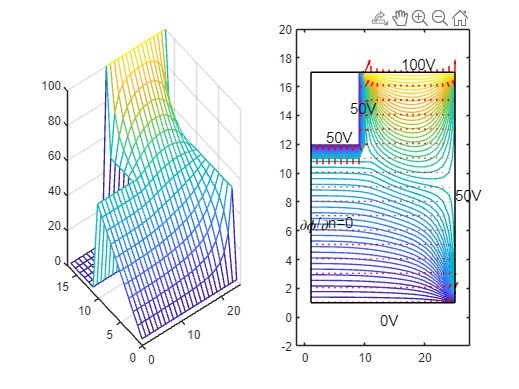

subplot(1,2,1),mesh(v1)                                     % 画三维曲面图
axis([0,25,0,17,0,100])
subplot(1,2,2),contour(v1,50)                               % 画等电位线图

hold on
x=1:1:hx;y=1:1:hy;
[xx,yy]=meshgrid(x,y);                                      % 形成栅格
[Gx,Gy]=gradient(v1,0.6,0.6);                               % 计算梯度
quiver(xx,yy,Gx,Gy,'r')                                     % 根据梯度数据画箭头
axis([-1.5,hx+2.5,-2,20])                                   % 设置坐标边框
plot([1,1,hx,hx,1],[1,hy,hy,1,1],'k')                       % 画导体边框
text(12.5,-0.2,'0V','fontsize',11);   
text(-1.2,6.5,'\partial\phi/\partialn=0','fontsize',11);        
text(25,8.5,'50V','fontsize',11); 
text(3.5,12.5,'50V','fontsize',11);
text(7.5,14.5,'50V','fontsize',11);
text(16,17.6,'100V','fontsize',11);
hold off